clear all;

- Genere una señal senoidal portadora de 20Hz y una señal de información cosenoidal moduladora de 2 Hz. 

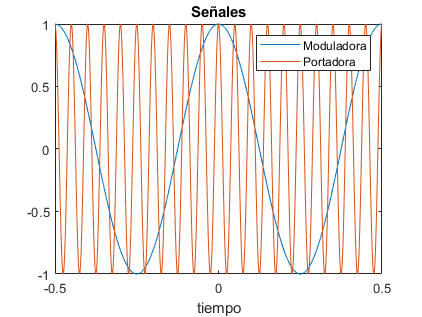

%Parametros
freq_port   =    20;            %Frecuencia de Portadora
freq_mod    =     2;            %Frecuencia de Moduladora
kps_64      = 64000;            %Muestreo
time        = -.5:1/kps_64:.5;  %Duracion de señal
%señal Portadora
port_sig    =  cos(2*pi*freq_port*time);
%señal moduladora
mod_sig     =   cos(2*pi*freq_mod*time);
% Señales en tiempo
figure(1);
plot(time, mod_sig)
hold on
plot(time, port_sig)
title('Señales a Mezclar');
xlabel('tiempo')
legend({'Moduladora','Portadora'},'Location','northeast')
hold off

## Modulacion AM con Doble Banda Lateral con Portadora Suprimida (DBLPS)

Indice de modulacion $\beta$

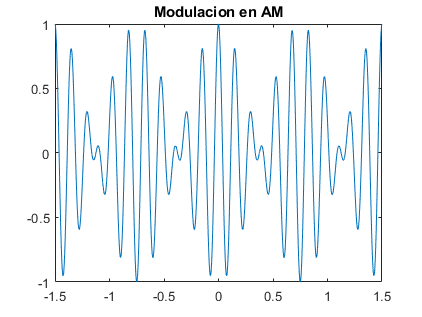

index_mod   =   .85;
range_freq  =   -kps_64/2:1:kps_64/2;
am_sig      =   port_sig.*mod_sig;
figure(2);
plot(time*3, am_sig);
title('Modulacion en AM');

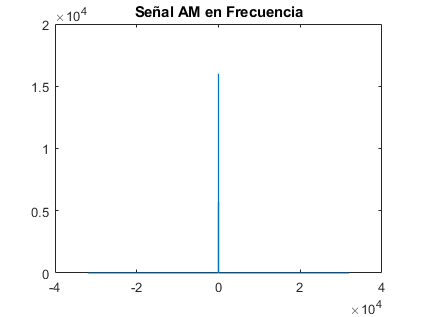

figure(3);
plot(range_freq,abs(ttof(am_sig)));
title('Señal AM en Frecuencia');